addpath 'E:\MATLAB'
addpath 'E:\MATLAB'\'IMAGE SETS'\
ImageNames={'aerial1.tiff';'aerial2.tiff';'aerial3.tiff';'aerial4.tiff';
    'baby.png';'bird.png';'woman.png';'zebra.png';'kodim03.png';'kodim10.png';
    'kodim15.png';'airplane.png';'arctichare.png';'girl.png';'lena.png';
    'monarch.png';'peppers1.tiff';'peppers2.png';'tulips.png'};
db1PSNR=zeros(size(ImageNames,1),1);
db2PSNR=zeros(size(ImageNames,1),1);
db3PSNR=zeros(size(ImageNames,1),1);
db4PSNR=zeros(size(ImageNames,1),1);

sym2PSNR=zeros(size(ImageNames,1),1);
sym3PSNR=zeros(size(ImageNames,1),1);
sym4PSNR=zeros(size(ImageNames,1),1);

coif2PSNR=zeros(size(ImageNames,1),1);
coif3PSNR=zeros(size(ImageNames,1),1);
coif4PSNR=zeros(size(ImageNames,1),1);

db1SSIM=zeros(size(ImageNames,1),1);
db2SSIM=zeros(size(ImageNames,1),1);
db3SSIM=zeros(size(ImageNames,1),1);
db4SSIM=zeros(size(ImageNames,1),1);

sym2SSIM=zeros(size(ImageNames,1),1);
sym3SSIM=zeros(size(ImageNames,1),1);
sym4SSIM=zeros(size(ImageNames,1),1);

coif2SSIM=zeros(size(ImageNames,1),1);
coif3SSIM=zeros(size(ImageNames,1),1);
coif4SSIM=zeros(size(ImageNames,1),1);

for i=1:size(ImageNames,1)
    string=char(ImageNames(i));
    B=imread(string);
    A=double(rgb2gray(B));
    [HR,HR2,HR3,HR4,HR5,HR6,HR7,HR8,HR9,HR10]=DWT2(A);
    db1PSNR(i)=psnr(uint8(A),uint8(HR));
    db2PSNR(i)=psnr(uint8(A),uint8(HR2));
    db3PSNR(i)=psnr(uint8(A),uint8(HR3));
    db4PSNR(i)=psnr(uint8(A),uint8(HR4));
  
    sym2PSNR(i)=psnr(uint8(A),uint8(HR5));
    sym3PSNR(i)=psnr(uint8(A),uint8(HR6));
    sym4PSNR(i)=psnr(uint8(A),uint8(HR7));
    
    coif2PSNR(i)=psnr(uint8(A),uint8(HR8));
    coif3PSNR(i)=psnr(uint8(A),uint8(HR9));
    coif4PSNR(i)=psnr(uint8(A),uint8(HR10));
    
    db1SSIM(i)=ssim(uint8(A),uint8(HR));
    db2SSIM(i)=ssim(uint8(A),uint8(HR2));
    db3SSIM(i)=ssim(uint8(A),uint8(HR3));
    db4SSIM(i)=ssim(uint8(A),uint8(HR4));
  
    sym2SSIM(i)=ssim(uint8(A),uint8(HR5));
    sym3SSIM(i)=ssim(uint8(A),uint8(HR6));
    sym4SSIM(i)=ssim(uint8(A),uint8(HR7));
    
    coif2SSIM(i)=ssim(uint8(A),uint8(HR8));
    coif3SSIM(i)=ssim(uint8(A),uint8(HR9));
    coif4SSIM(i)=ssim(uint8(A),uint8(HR10));
end
toc

Elapsed time is 1909.305606 seconds.


T=table(ImageNames,db1PSNR,db2PSNR,db3PSNR,db4PSNR,sym2PSNR, ...
    sym3PSNR,sym4PSNR,coif2PSNR,coif3PSNR,coif4PSNR,db1SSIM, ...
    db2SSIM,db3SSIM,db4SSIM,sym2SSIM,sym3SSIM,sym4SSIM,coif2SSIM, ...
    coif3SSIM,coif4SSIM)

T = 19×21 table
        ImageNames        db1PSNR    db2PSNR    db3PSNR    db4PSNR    sym2PSNR    sym3PSNR    sym4PSNR    coif2PSNR    coif3PSNR    coif4PSNR    db1SSIM    db2SSIM    db3SSIM    db4SSIM    sym2SSIM    sym3SSIM    sym4SSIM    coif2SSIM    coif3SSIM    coif4SSIM
    __________________    _______    _______    _______    _______    ________    ________    ________    _________    _________    _________    _______    

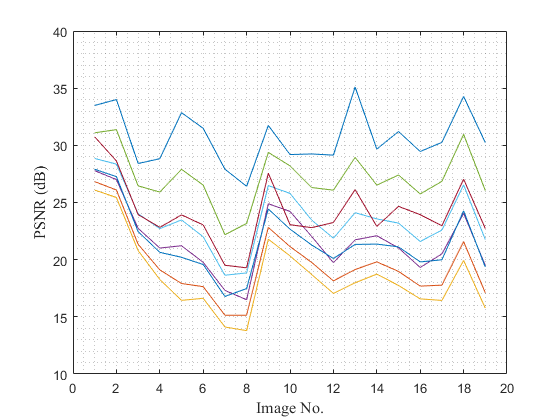

Table_location='E:\MATLAB\Results';
path_format = [Table_location '\WaveletReconstruction.xlsx'];
writetable(T,path_format)
n=1:size(ImageNames);
figure;
plot(n,db1PSNR,n,db2PSNR,n,db3PSNR,n,db4PSNR,n,sym2PSNR,n,sym3PSNR,n,sym4PSNR,n,coif2PSNR,n,coif3PSNR,n,coif4PSNR)
xlabel ('Image No.',"FontSize",12,"FontName",'Times New Roman')
ylabel ('PSNR (dB)',"FontSize",12,"FontName",'Times New Roman')
grid minor

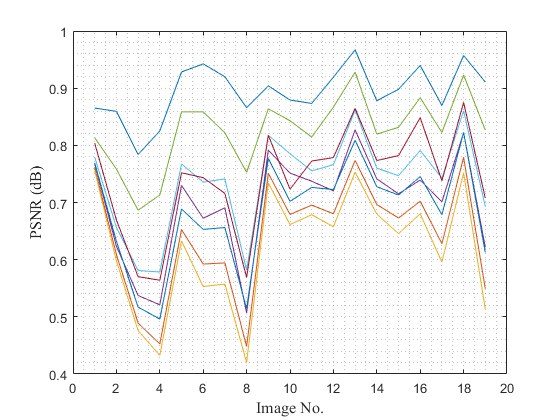

figure;
plot(n,db1SSIM,n,db2SSIM,n,db3SSIM,n,db4SSIM,n,sym2SSIM,n,sym3SSIM,n,sym4SSIM,n,coif2SSIM,n,coif3SSIM,n,coif4SSIM)
xlabel ('Image No.',"FontSize",12,"FontName",'Times New Roman')
ylabel ('PSNR (dB)',"FontSize",12,"FontName",'Times New Roman')
grid minor

function [HR,HR2,HR3,HR4,HR5,HR6,HR7,HR8,HR9,HR10]= DWT2 (R)
k=2;
LR=KipkoechDownSampling(R,k);
LRPrefiltered=KipkoechCubicBSplinesPrefilter(LR);
A=KipkoechBSplinesInterpolation(LRPrefiltered,k);

LR=imresize(A,0.5, 'nearest');
[~,LH,HL,HH]=dwt2(A,'db1');
HR=idwt2(LR.*2,LH,HL,HH,'db1');

[LL2,LH2,HL2,HH2]=dwt2(A,'db2');
[M,N]=size(LL2);
LL21=imresize(A,[M,N]);
HR2=idwt2(LL21.*2,LH2,HL2,HH2,'db2');

[LL3,LH3,HL3,HH3]=dwt2(A,'db3');
[M1,N1]=size(LL3);
LL31=imresize(A,[M1,N1]);
HR3=idwt2(LL31.*2,LH3,HL3,HH3,'db3');

[LL4,LH4,HL4,HH4]=dwt2(A,'db4');
[M2,N2]=size(LL4);
LL41=imresize(A,[M2,N2]);
HR4=idwt2(LL41.*2,LH4,HL4,HH4,'db4');

[LL5,LH5,HL5,HH5]=dwt2(A,'sym2');
[M2,N2]=size(LL5);
LL51=imresize(A,[M2,N2]);
HR5=idwt2(LL51.*2,LH5,HL5,HH5,'sym2');

[LL6,LH6,HL6,HH6]=dwt2(A,'sym3');
[M2,N2]=size(LL6);
LL61=imresize(A,[M2,N2]);
HR6=idwt2(LL61.*2,LH6,HL6,HH6,'sym3');


[LL7,LH7,HL7,HH7]=dwt2(A,'sym4');
[M2,N2]=size(LL7);
LL71=imresize(A,[M2,N2]);
HR7=idwt2(LL71.*2,LH7,HL7,HH7,'sym4');

[LL8,LH8,HL8,HH8]=dwt2(A,'coif2');
[M2,N2]=size(LL8);
LL81=imresize(A,[M2,N2]);
HR8=idwt2(LL81.*2,LH8,HL8,HH8,'coif2');

[LL9,LH9,HL9,HH9]=dwt2(A,'coif3');
[M2,N2]=size(LL9);
LL91=imresize(A,[M2,N2]);
HR9=idwt2(LL91.*2,LH9,HL9,HH9,'coif3');

[LL10,LH10,HL10,HH10]=dwt2(A,'coif4');
[M2,N2]=size(LL10);
LL101=imresize(A,[M2,N2]);
HR10=idwt2(LL101.*2,LH10,HL10,HH10,'coif4');
end
